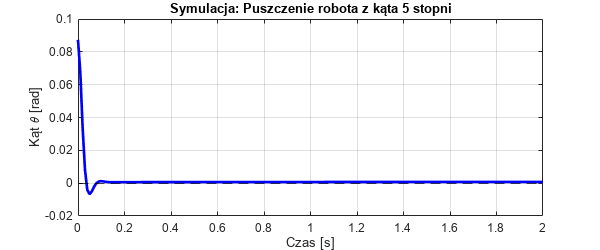


kat_start_stopnie = 5;
Tf = 0.01;
czas_symulacji = 2;

Kp_sim = Kp; 
Ki_sim = Ki;
Kd_sim = Kd; 

Sys_plant = ss(A, B, C, D);

Regulator = pid(Kp_sim, Ki_sim, Kd_sim, Tf);

Sys_closed = feedback(Sys_plant * Regulator, 1);

% warunek początkowy
% (Robot=4 + PID=2 = 6 stanów)
num_states = size(Sys_closed.A, 1);
x0 = zeros(num_states, 1);

% A: x(1)=x, x(2)=theta.
x0(2) = deg2rad(kat_start_stopnie); 

t = 0:0.01:czas_symulacji;
[y, t] = initial(Sys_closed, x0, t);

figure('Position', [100, 100, 600, 250]);
plot(t, y, 'b', 'LineWidth', 2);
grid on;
title(['Symulacja: Puszczenie robota z kąta ' num2str(kat_start_stopnie) ' stopni']);
xlabel('Czas [s]');
ylabel('Kąt \theta [rad]');
yline(0, 'k--');

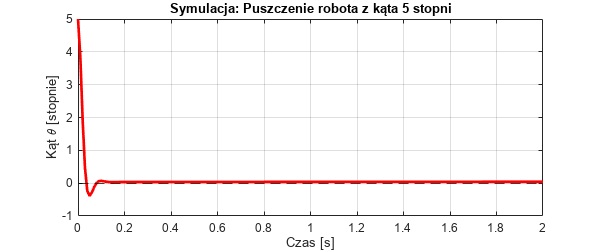


figure('Position', [100, 100, 600, 250]);
plot(t, rad2deg(y), 'r', 'LineWidth', 2);
grid on;
title(['Symulacja: Puszczenie robota z kąta ' num2str(kat_start_stopnie) ' stopni']);
xlabel('Czas [s]');
ylabel('Kąt \theta [stopnie]');
yline(0, 'k--');
print('Puszczenie robota zigler.png', '-dpng', '-r400');